### Comparing our measurements of lower lip fluorescence to other published data on oral mucosal tissue 

%{
cd /Users/joyce/Github/isetcam; addpath(genpath(pwd));
cd /users/joyce/Github/oraleye/; addpath(genpath(pwd));
cd /users/joyce/Github/isetfluorescence/; addpath(genpath(pwd));
cd /users/joyce/Github/oe_tongue_lip/; addpath(genpath(pwd));
%}

ieInit;
wave = 500:585;

de Veld, D. C., Skurichina, M., Witjes, M. J., Duin, R. P., Sterenborg, D. J., Star, W. M., & Roodenburg, J. L. (2003).  Autofluorescence characteristics of healthy oral mucosa at different anatomical sites. Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 32(5), 367-376

Figure 4, "Mean autofluorescence spectra of healthy oral mucosa obtained at four representative locations, excitation wavelength 405 nm" , cheek mucosa and the dorsal side of the tongue

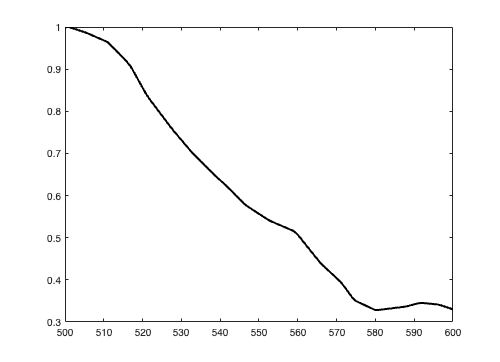

mucosa = ieReadSpectra('CheekVeld2003.mat',wave); 
ieNewGraphWin; plot(wave,mucosa/max(mucosa(:)),'k','lineWidth',2); hold on;

Betz, C. S., Mehlmann, M., Rick, K., Stepp, H., Grevers, G., Baumgartner, R., & Leunig, A. (1999). Autofluorescence imaging and spectroscopy of normal and malignant mucosa in patients with head and neck cancer, Lasers in Surgery and Medicine: The Official Journal of the American Society for Laser Medicine and Surgery, 25(4), 323-334.

Figure 3 Averaged autofluorescence spectra from 36 patients for "healthy tissue" adjacent to malignant tissue.  I only digitized the data for healthy tissue

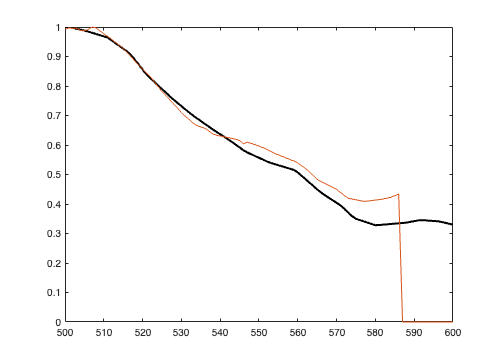

mucosa = ieReadSpectra('Betz1999.mat',wave);
plot(wave,mucosa/max(mucosa(:)),'r','lineWidth',2); 

Van Staveren, H. J., Van Veen, R. L. P., Speelman, O. C., Witjes, M. J. H., Star, W. M., & Roodenburg, J. L. N. (2000). Classification of clinical autofluorescence spectra of oral leukoplakia using an artificial neural network: a pilot study.  Oral oncology, 36(3), 286-293.

data from Figure 3 as example of oral mucosa with 420 excitation, surrounding "normal" tissue ...' 

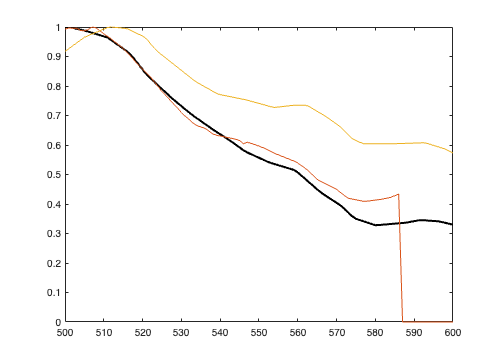

mucosa = ieReadSpectra('VanStaveren2000.mat',wave);
plot(wave,mucosa/max(mucosa(:))); 

Roy, K., Bottrill, I., Ingrams, D. R., Pankratov, M. M., Rebeiz, E. E., Woo, P., & Feld, M. S. (1995, May) Diagnostic fluorescence spectroscopy of oral mucosa. In Lasers in Surgery: Advanced Characterization, Therapeutics, and Systems V (Vol. 2395, pp. 135-142). SPIE.

from Figure 6 ("typical normal oral mucosa emission")

mucosa = ieReadSpectra('Roy1995.mat',wave);
plot(wave,mucosa/max(mucosa(:)),'g','lineWidth',2); ; 
 

## Read a couple of raw data sets

This is the database of raw measurements.

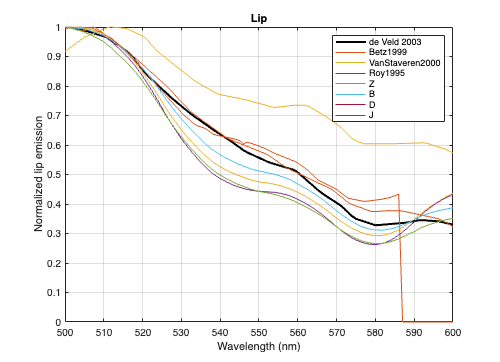

[T,dataDir] = oeDatabaseCreate;

files405Z = ieTableGet(T,'subject','Z','substrate','lip','e wave',405,'e level',980,'return','files');
files405B = ieTableGet(T,'subject','B','substrate','lip','e wave',405,'e level',980,'return','files');
files405D = ieTableGet(T,'subject','D','substrate','lip','e wave',405,'e level',980,'return','files');
files405J = ieTableGet(T,'subject','J','substrate','lip','e wave',405,'e level',980,'return','files');
lipFiles = cat(1,files405Z,files405B,files405D,files405J);

lipData = zeros(numel(wave),numel(lipFiles));

for ii=1:numel(lipFiles)
    data = ieReadSpectra(fullfile(dataDir,lipFiles{ii}),wave); 
    lipData (:,ii) = data(:);
    plot(wave,data/max(data(:))); hold on;
end
legend({'de Veld 2003','Betz1999','VanStaveren2000','Roy1995','Z','B','D','J'});
title('Lip');
xlabel('Wavelength (nm)'); ylabel('Normalized lip emission'); grid on;